% n=2;
% q = sym('q', [n, 1]);
% for i=1:n
%     nomeVariabile = ['q' num2str(i)];
%     assignin('base', nomeVariabile,q(i,1));
% end
% qd = sym('qd', [n, 1]);
% for i=1:n
%     nomeVariabile = ['qd' num2str(i)];
%     assignin('base', nomeVariabile,qd(i,1));
% end
% 
% syms a1 a2 a3 a4 real;
% a=[a1; a2; a3];

Definiamo la matrice di Inerzia

% M=[a1+2*a2*q2+a3*q2^2+2*a4*q2*sin(q3)+a5*sin(q3)^2 0 0 ; 0 a3 a4*cos(q3); 0 a4*cos(q3) a6];
%M=[a1 -a3*sin(q2);-a3*sin(q2) a2]
%c
syms A B C q2;
M=[A B*cos(q2);B*cos(q2) C]; n=2; a=[A;B;C]

$$a = \left(\begin{array}{c} A\\ B\\ C \end{array}\right)$$

Aggiungi altri termini del modello se presenti:

% a=[a1;a2;a3;a4;a5];
M

$$M = \left(\begin{array}{cc} A & B\,\cos\left(q_{2}\right)\\ B\,\cos\left(q_{2}\right) & C \end{array}\right)$$

%c
%gravity_terms_parametrized

thereis_c=false;
thereis_g=false;

Noi dobbiamo trovare il regressor presente nell' espressione:

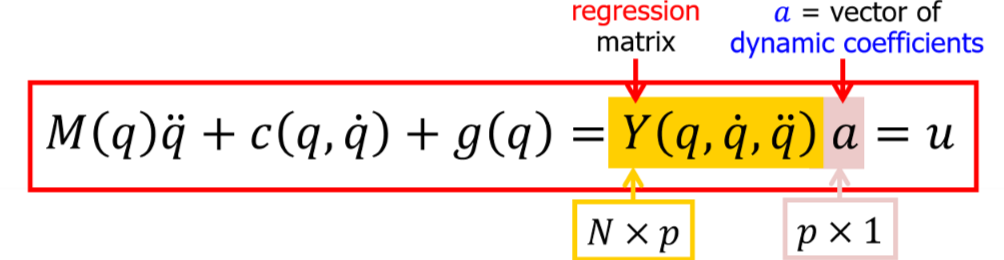

Quindi calcoliamo il modello nella forma che ci serve

qdd=sym('dqq',[n,1]);

if(thereis_c)
    if(thereis_g)
        Model_exp=simplify(M*qdd+c+gravity_terms_parametrized)
    else
        Model_exp=simplify(M*qdd+c)
    end
else
    Model_exp=simplify(M*qdd)
end

$$Model\_exp = \left(\begin{array}{c} A\,{\mathrm{dqq}}_{1}+B\,{\mathrm{dqq}}_{2}\,\cos\left(q_{2}\right)\\ C\,{\mathrm{dqq}}_{2}+B\,{\mathrm{dqq}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

Nota che ha dimensione nx1.

Adesso estraiamo i coefficienti che moltiplicano i dynamic coefficients e costruiamo il regressor:

Y=sym('Y',[n,size(a)]);



for i=1:n
    for j=1:size(a) 

        coeff_of_dyn_coeff=coeffs(Model_exp(i,1),a(j,1));
        % è un vettore dove il primo elemento non dipende da var,
        % il secondo ha dipendenza lineare, il terzo quadratica e cosi via

        var_funzionale=size(coeff_of_dyn_coeff); %numero di colonne del vettore che contiene i coefficienti 

        if(var_funzionale(1,2)>1)
            Y(i,j)=coeff_of_dyn_coeff(1,2);
        else
            Y(i,j)=0;
        end

    end
end
simplify(Y) %deve avere dimensione n x num_para

$$ans = \left(\begin{array}{ccc} {\mathrm{dqq}}_{1} & {\mathrm{dqq}}_{2}\,\cos\left(q_{2}\right) & 0\\ 0 & {\mathrm{dqq}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{dqq}}_{2} \end{array}\right)$$

a

$$a = \left(\begin{array}{c} A\\ B\\ C \end{array}\right)$$